# Writing an ODE Function for a Third-Order ODE

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE and visualizes the solution.

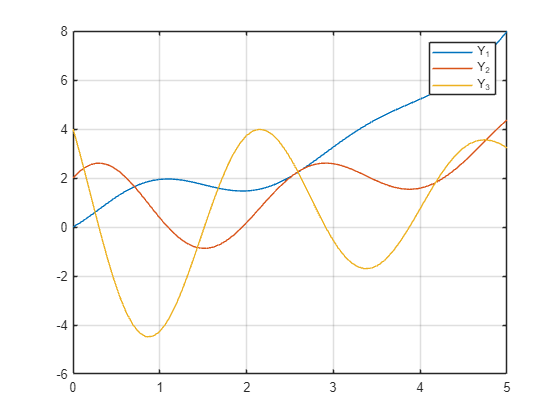

% Solve the system of ODEs
tRange = [0 5];
Y0 = [0;2;4];
[tSol, YSol] = ode45(@thirdOrder, tRange, Y0);

% Visualize solution
Y1 = YSol(:, 1);
Y2 = YSol(:, 2);
Y3 = YSol(:, 3);
plot(tSol, Y1, tSol, Y2, tSol, Y3);
grid on
legend("Y_1", "Y_2", "Y_3")

## Task 1

Follow the steps below to re-write any third-order ODE as a system of three first-order ODEs.

- If *y* appears in the ODE, re-write it as *Y*1.

- If *d**y/d**t* appears in the ODE, re-write it as *Y*2.

- If *d^*2*y/dt^*2 appears in the ODE, re-write it as *Y*3.

- Re-write the third derivative as *d**Y*3/*d**t*.

Your three first-order ODEs should only contain variables *Y*1, *Y*2, and *Y*3

function dYdt = thirdOrder(t, Y)
    % Extract Y1, the first element of Y
    Y1 = Y(1);
    
    % Extract Y2, the second element of Y
    Y2 = Y(2);
    
    % Extract Y3, the third element of Y
    Y3 = Y(3);
    
    % TODO - Complete expression for dY1dt.
    dY1dt = Y2;
    
    % TODO - Complete expression for dY2dt
    dY2dt = Y3;
    
    % TODO - Complete expression for dY3dt
    dY3dt = -6*Y2 + 3*Y1;
    
    % TODO - Create dYdt, column vector containing dY1dt, dY2dt, and dY3dt
    dYdt = [dY1dt; dY2dt; dY3dt];
end